addpath(fullfile("Models","siamese_vggface"));

datasetFolder = fullfile("FaceDatabase","lfw-funneled-scaled-150");
dataDetailsFolder = fullfile("Proprocessing","lfw-details");

% peopleGT2IMG_file = fullfile(dataDetailsFolder,"peopleGT2Images.csv"); % list of people greater or equal to 2 images

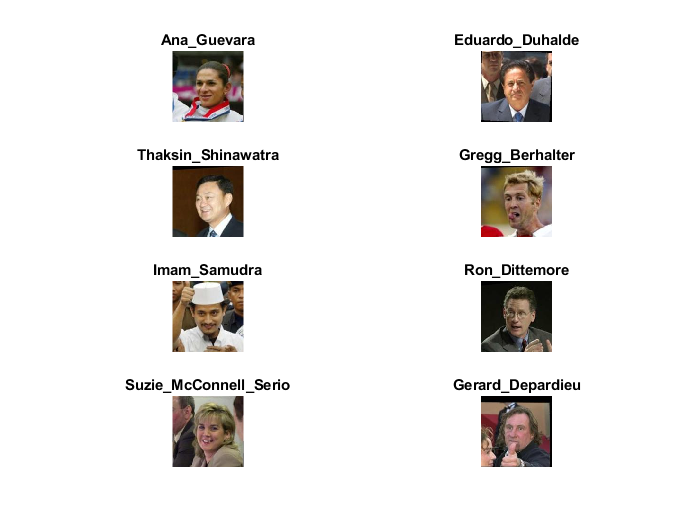

imdsTrain = imageDatastore(datasetFolder, ...
    "IncludeSubfolders",true, ...
    "LabelSource","foldernames");

% show random images
idx = randperm(numel(imdsTrain.Files),8);
for i = 1:numel(idx)
    subplot(4,2,i)
    imshow(readimage(imdsTrain,idx(i)))
    title(imdsTrain.Labels(idx(i)),"Interpreter","none");
end

% THIS WAS BEING USED FOR FILTERING PEOPLE WITH MORE THAN 2 IMAGES, BUT
% SUPERCEEDED BY EXTRA IMIPLEMENTATION WITHIN getSimilarPair
% this problem need to be solved as some subject only has a single image
% that cannot be used to generate similar pair

% if ~exist(peopleGT2IMG_file, "file")
%     addpath("Proprocessing");
%     tb = readPeopleText(fullfile(dataDetailsFolder,"people.txt"));
%     writetable(tb(tb.instance > 1, :),fullfile(dataDetailsFolder,"peopleGT2Images.csv"));
% end
% peopleGT2IMG_table = readtable(peopleGT2IMG_file);
% peopleGT2IMG_table

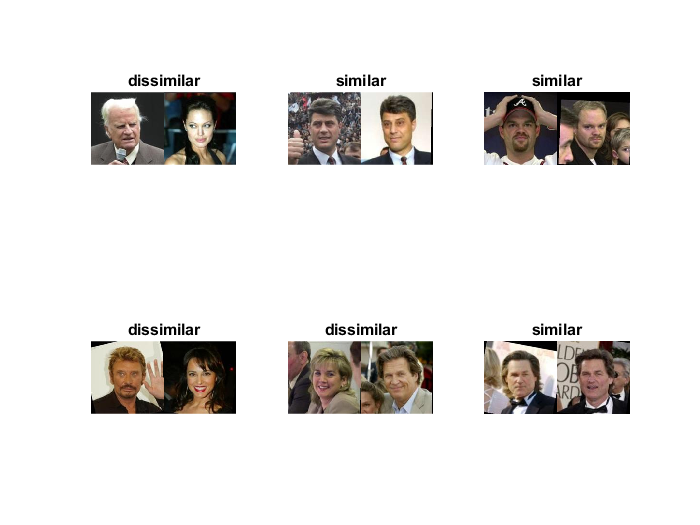

% generate pairs of images

batchSize = 6;
[pairImage1,pairImage2,pairLabel] = getSiameseBatch(imdsTrain,batchSize);
figure;
for i = 1:batchSize
    if pairLabel(i) == 1
        s = "similar";
    else
        s = "dissimilar";
    end
    subplot(2,3,i)
    imshow([pairImage1(:,:,:,i)/255 pairImage2(:,:,:,i)/255]);
    title(s)
end

% params = load(fullfile("ModelWeights","siamese_vggface","siamese_vggface_weights.mat"));

layers = [
    
    imageInputLayer([150 150 3],"Name","input","Normalization","none")
    
    convolution2dLayer([10 10],32,"Name","conv2d_1","WeightsInitializer","narrow-normal","BiasInitializer","narrow-normal")
    reluLayer("Name","relu_1")
    maxPooling2dLayer(2,"Name","maxpool2d_1","Stride",2)
    
    convolution2dLayer([7 7],64,"Name","conv2d_2","WeightsInitializer","narrow-normal","BiasInitializer","narrow-normal")
    reluLayer("Name","relu_2")
    maxPooling2dLayer(2,"Name","maxpool2d_2","Stride",2)
    
    convolution2dLayer([4 4],64,"Name","conv2d_3","WeightsInitializer","narrow-normal","BiasInitializer","narrow-normal")
    reluLayer("Name","relu_3")
    maxPooling2dLayer(2,"Name","maxpool2d_3","Stride",2)
    
    convolution2dLayer([5 5],128,"Name","conv2d_4","WeightsInitializer","narrow-normal","BiasInitializer","narrow-normal")
    reluLayer("Name","relu_4")
    
    fullyConnectedLayer(2048,"Name","fc_1","WeightsInitializer","narrow-normal","BiasInitializer","narrow-normal")

    ];

lgraph = layerGraph(layers);

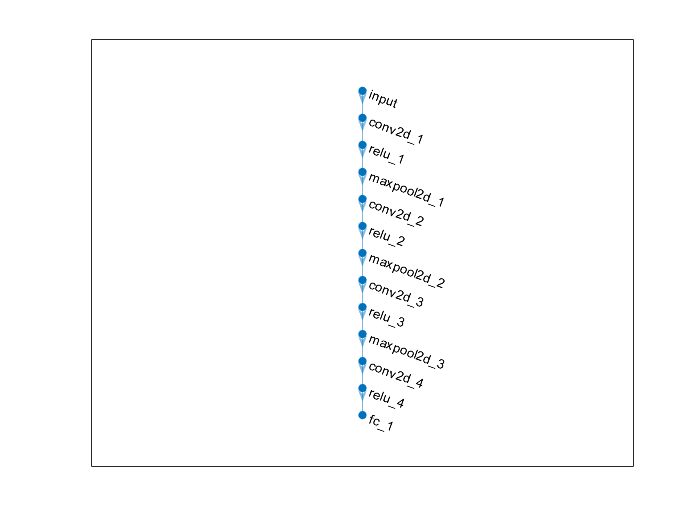

figure 
plot(lgraph);

net = dlnetwork(lgraph);

fcWeights = dlarray(0.01*randn(1,2048));
fcBias = dlarray(0.01*randn(1,1));

fcParams = struct(...
    "FcWeights",fcWeights,...
    "FcBias",fcBias);

% Training Setup

numIterations = 10000;
miniBatchSize = 64; % change this to a smaller value if your gpu cant handle it

learningRate = 6e-5;
gradDecay = 0.9;
gradDecaySq = 0.99;

executionEnvironment = "auto";
% executionEnvironment = "cpu";

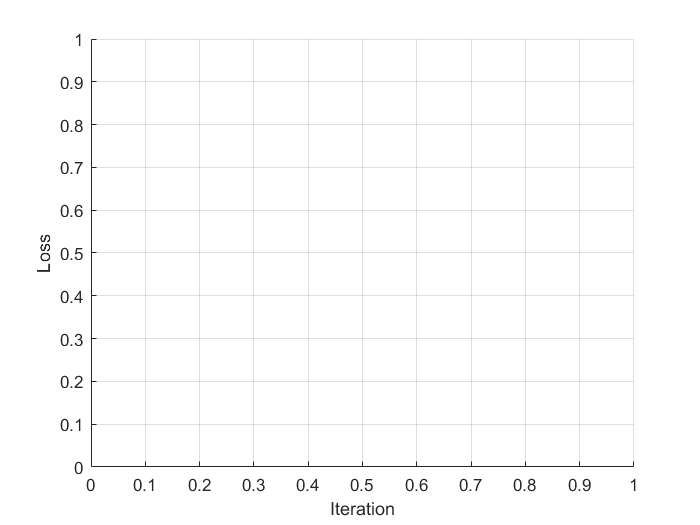

figure
C = colororder;
lineLossTrain = animatedline("Color",C(2,:));
ylim([0 inf])
xlabel("Iteration")
ylabel("Loss")
grid on

trailingAvgSubnet = [];
trailingAvgSqSubnet = [];
trailingAvgParams = [];
trailingAvgSqParams = [];

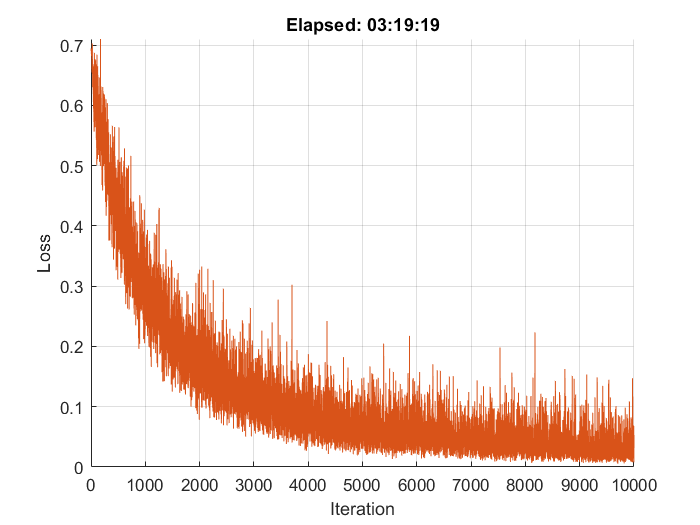

start = tic;

% Loop over mini-batches.
for iteration = 1:numIterations

    % Extract mini-batch of image pairs and pair labels
    [X1,X2,pairLabels] = getSiameseBatch(imdsTrain,miniBatchSize);
    
    % Convert mini-batch of data to dlarray. Specify the dimension labels
    % "SSCB" (spatial, spatial, channel, batch) for image data
    X1 = dlarray(X1,"SSCB");
    X2 = dlarray(X2,"SSCB");

    % If training on a GPU, then convert data to gpuArray.
    if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
        X1 = gpuArray(X1);
        X2 = gpuArray(X2);
    end

    % Evaluate the model loss and gradients using dlfeval and the modelLoss
    % function listed at the end of the example.
    [loss,gradientsSubnet,gradientsParams] = dlfeval(@modelLoss,net,fcParams,X1,X2,pairLabels);

    % Update the Siamese subnetwork parameters.
    [net,trailingAvgSubnet,trailingAvgSqSubnet] = adamupdate(net,gradientsSubnet, ...
        trailingAvgSubnet,trailingAvgSqSubnet,iteration,learningRate,gradDecay,gradDecaySq);

    % Update the fullyconnect parameters.
    [fcParams,trailingAvgParams,trailingAvgSqParams] = adamupdate(fcParams,gradientsParams, ...
        trailingAvgParams,trailingAvgSqParams,iteration,learningRate,gradDecay,gradDecaySq);

    % Update the training loss progress plot.
    D = duration(0,0,toc(start),"Format","hh:mm:ss");
    lossValue = double(extractdata(loss));
    addpoints(lineLossTrain,iteration,lossValue);
    title("Elapsed: " + string(D))
    drawnow
end

save('net.mat', 'net');
save('fcParams.mat','fcParams');